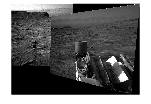

Unrecognized function or variable 'testMarsImage'.

% Read the images
fixedImg = imread("C:\Users\xxoox\OneDrive\デスクトップ\MATLAB works\Computer Vision for Engineering and Science\C1-IntroductionToComputerVision\Module 4\sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");
movingImg = imread("C:\Users\xxoox\OneDrive\デスクトップ\MATLAB works\Computer Vision for Engineering and Science\C1-IntroductionToComputerVision\Module 4\sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");

% Convert images to grayscale
fixedGray = im2gray(fixedImg);
movingGray = im2gray(movingImg);

% Detect features in both images
fixedPoints = detectSURFFeatures(fixedGray);
movingPoints = detectSURFFeatures(movingGray);

% Extract features from both images
[fixedFeatures, fixedValidPoints] = extractFeatures(fixedGray, fixedPoints);
[movingFeatures, movingValidPoints] = extractFeatures(movingGray, movingPoints);

% Match features by using their descriptors
indexPairs = matchFeatures(fixedFeatures, movingFeatures);

% Retrieve locations of corresponding points for each image
fixedMatchedPoints = fixedValidPoints(indexPairs(:,1), :);
movingMatchedPoints = movingValidPoints(indexPairs(:,2), :);

% Estimate the transformation between the moving and fixed images
tform = estimateGeometricTransform(movingMatchedPoints, fixedMatchedPoints, 'projective');

% Compute the output limits for each transform
[xLimits, yLimits] = outputLimits(tform, [1 size(movingImg, 2)], [1 size(movingImg, 1)]);

% Find the minimum and maximum output limits
xMin = min([1; xLimits(:)]);
xMax = max([size(fixedImg, 2); xLimits(:)]);
yMin = min([1; yLimits(:)]);
yMax = max([size(fixedImg, 1); yLimits(:)]);

% Initialize the "empty" panorama
width = round(xMax - xMin);
height = round(yMax - yMin);
panorama = zeros([height width], 'like', fixedGray);

% Warp the moving image onto the panorama canvas
warpedMovingImg = imwarp(movingGray, tform, 'OutputView', imref2d([height, width], [xMin, xMax], [yMin, yMax]));

% Copy the fixed image in the panorama
panorama(1:size(fixedGray, 1), 1:size(fixedGray, 2)) = fixedGray;

% Overlay the warped moving image onto the panorama
overlayIdx = warpedMovingImg > 0;
panorama(overlayIdx) = warpedMovingImg(overlayIdx);

% Display the panorama
figure;
imshow(panorama);
title('Panorama');